%{
Program to inpaint images using low rank completion methods
Harsh Shah and Pranava Singhal 
%}

addpath '.\MMread';
rng(73);

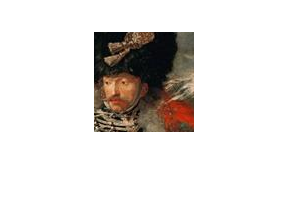


img = imread('data/painting.jpg');
img = double(img(150:249,250:349, :))/255;
imshow(img)



H = size(img,1);
W = size(img,2);
block_size = 5;

obs = 0.7;
mask_1 = binornd(1,obs, [floor(H/block_size),floor(W/block_size)]);
mask = zeros(H,W);
for i = block_size:block_size:H
    for j = block_size:block_size:W
        mask(i-block_size+1:i,j-block_size+1:j) = mask_1(floor(i/block_size),floor(j/block_size));
    end
end

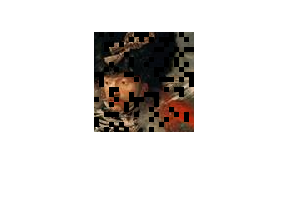

img_f = (img);
imshow(img_f.*mask)

patch_size = 8;
stride = 4;
img_patches = generatePatches_overlapping(img, patch_size, stride);
mask_patches = generatePatches_overlapping(mask, patch_size, stride);


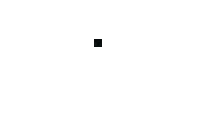

imshow(img_patches(:,:,:,1));

img_concat = concatPatches(img_patches);
mask_concat = concatPatches(mask_patches);
mu_list = [0.01, 0.1, 1, 10, 100]

mu_list =     0.0100    0.1000    1.0000   10.0000  100.0000


p_norm = 0.5;
frame = zeros([size(img_concat),size(mu_list)]);
frame_2 = zeros([size(img_concat),size(mu_list)]);
for j = 1:size(mu_list,2)
    for c = 1:3
        frame(:,:,c, j) = fixed_point_minimization(mask_concat, img_concat(:,:,c), mu_list(j),-1,-1,-1);
        frame_2(:,:,c, j) = reweighted_fixed_point_minimization(mask_concat, img_concat(:,:,c), mu_list(j),-1,-1,-1, p_norm);
    end
end

completed
completed
completed
completed
completed
completed
completed
completed
completed
completed
completed
completed
completed
completed
completed


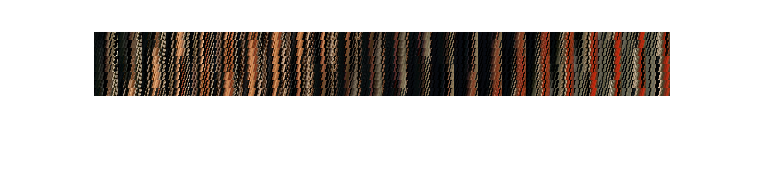

imshow(frame(:,:,:,1));

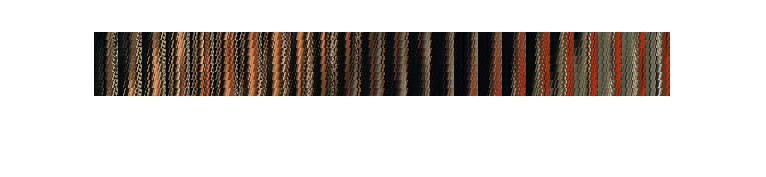

imshow(frame(:,:,:,2));

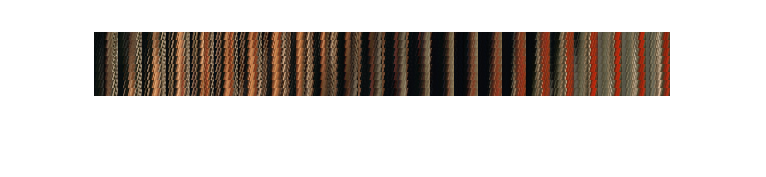

imshow(frame(:,:,:,3));

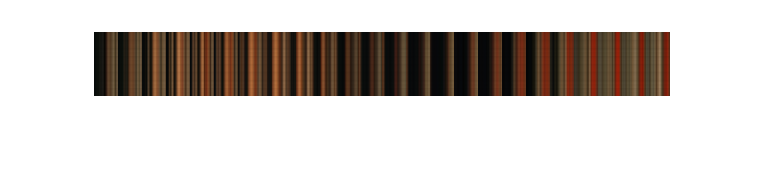

imshow(frame(:,:,:,4));

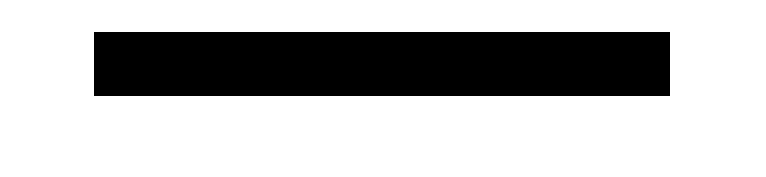

imshow(frame(:,:,:,5));

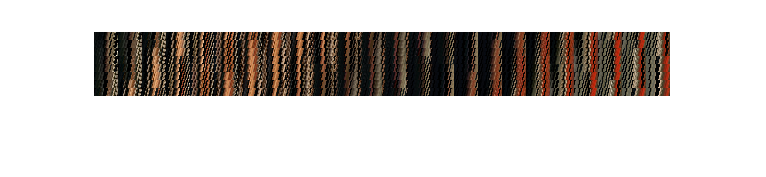

imshow(frame_2(:,:,:,1));

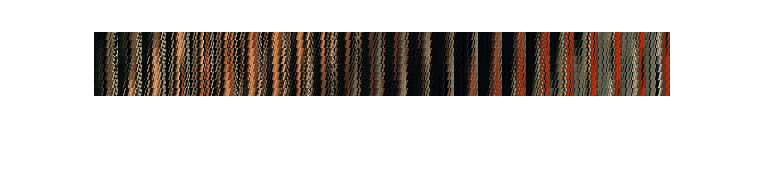

imshow(frame_2(:,:,:,2));

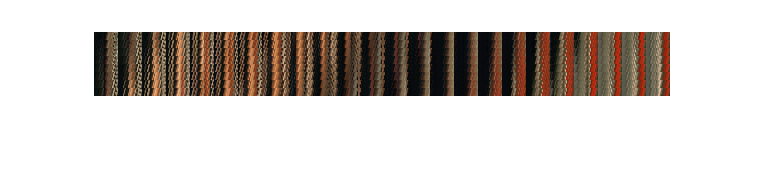

imshow(frame_2(:,:,:,3));

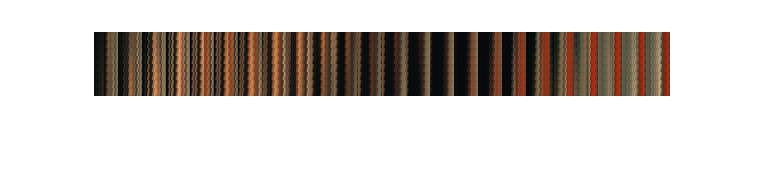

imshow(frame_2(:,:,:,4));

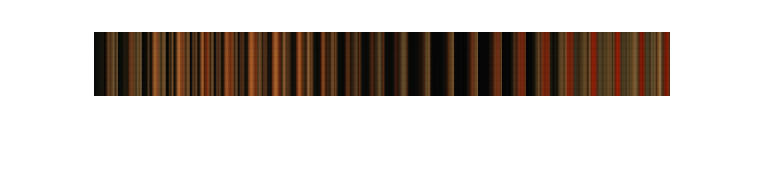

imshow(frame_2(:,:,:,5));

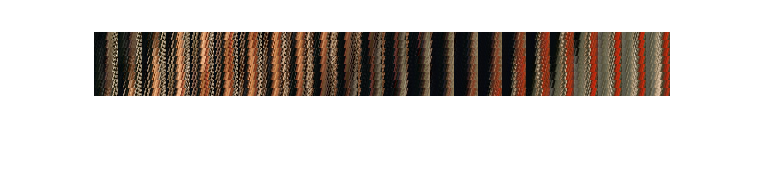

imshow(img_concat);

x_patches = (W - patch_size + stride)/stride;
y_patches = (H - patch_size + stride)/stride;
num_channels = size(frame, 3);
num_patches = size(frame, 2);

frame_reshaped = zeros( num_patches,patch_size, patch_size, num_channels, size(mu_list,2));
for j = 1:size(mu_list,2)
    frame_reshaped(:,:,:,:,j) = permute(reshape(permute(frame(:,:,:,j), [1 3 2]), patch_size, patch_size, num_channels, num_patches), [4 1 2 3]);
end

frame_2_reshaped = zeros( num_patches,patch_size, patch_size, num_channels, size(mu_list,2));
for j = 1:size(mu_list,2)
    frame_2_reshaped(:,:,:,:,j) = permute(reshape(permute(frame_2(:,:,:,j), [1 3 2]), patch_size, patch_size, num_channels, num_patches), [4 1 2 3]);
end

frame_recons = zeros(H,W,num_channels, size(mu_list,2));
for j = 1:size(mu_list,2)
    frame_recons(:,:,:,j) = imageReconstruction_overlapping(frame_reshaped(:,:,:,:,j), x_patches, y_patches, stride);
end

frame__2_recons = zeros(H,W,num_channels, size(mu_list,2));
for j = 1:size(mu_list,2)
    frame_2_recons(:,:,:,j) = imageReconstruction_overlapping(frame_2_reshaped(:,:,:,:,j), x_patches, y_patches, stride);
end

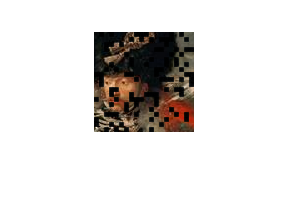

imshow(frame_recons(:,:,:,1))

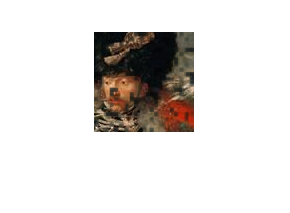

imshow(frame_recons(:,:,:,2))

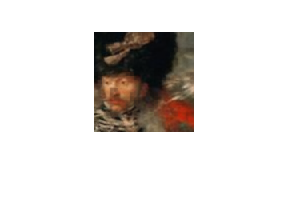

imshow(frame_recons(:,:,:,3))

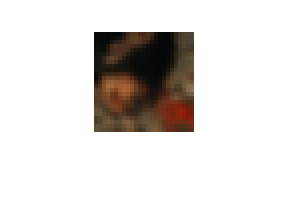

imshow(frame_recons(:,:,:,4))

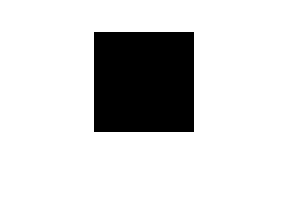

imshow(frame_recons(:,:,:,5))

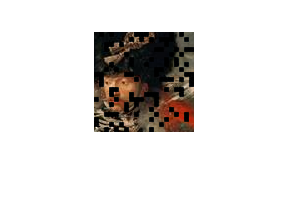

imshow(frame_2_recons(:,:,:,1))

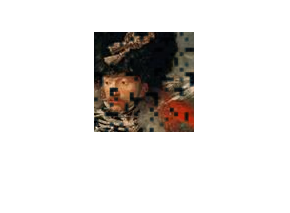

imshow(frame_2_recons(:,:,:,2))

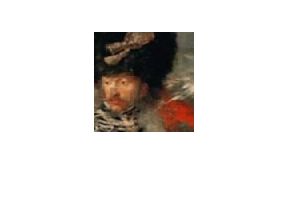

imshow(frame_2_recons(:,:,:,3))

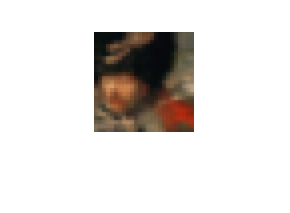

imshow(frame_2_recons(:,:,:,4))

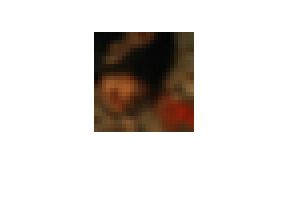

imshow(frame_2_recons(:,:,:,5))

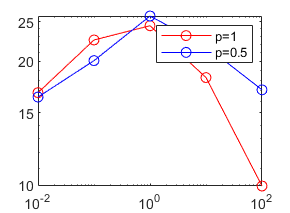

psnr = zeros(size(mu_list));
rmse = zeros(size(mu_list));
psnr_2 = zeros(size(mu_list));
rmse_2 = zeros(size(mu_list));
for j = 1:size(mu_list,2)
    psnr(j) = PSNR(img, frame_recons(:,:,:,j));
    rmse(j) = RMSE(img, frame_recons(:,:,:,j));
    psnr_2(j) = PSNR(img, frame_2_recons(:,:,:,j));
    rmse_2(j) = RMSE(img, frame_2_recons(:,:,:,j));
end
loglog(mu_list, psnr,'-or',mu_list, psnr_2,'-ob')
legend('p=1','p=0.5')

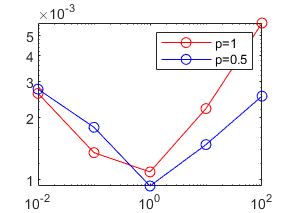

loglog(mu_list, rmse,'-or',mu_list, rmse_2,'-ob')
legend('p=1','p=0.5')

function result = concatPatches(patches)
    patch_size = size(patches,1);
    num_patches = size(patches,4);
    num_channels = size(patches,3);
    columns = reshape(patches, [patch_size*patch_size, num_channels, num_patches]);
    colcel = num2cell(columns,[1,2]);
    concatenated = cat(3,colcel{:});
    result = permute(concatenated,[1,3,2]);
end

function result = imageReconstruction_overlapping(all_patches, x_patches, y_patches, stride)
    all_patches_size = size(all_patches);
    patch_dim = all_patches_size(2);
    T = all_patches_size(4);
    height = patch_dim + stride*(y_patches-1);
    width = patch_dim + stride*(x_patches-1);
    
    reconstruction = zeros(height, width, T);
    count_mat = zeros(height, width, T);
    for i = 1:x_patches
        for j = 1:y_patches
            reconstruction((j-1)*stride+1:(j-1)*stride+patch_dim, (i-1)*stride+1:(i-1)*stride+patch_dim, :) = reconstruction((j-1)*stride+1:(j-1)*stride+patch_dim, (i-1)*stride+1:(i-1)*stride+patch_dim, :) + squeeze(all_patches((i-1)*y_patches + j, :, :, :));
            count_mat((j-1)*stride+1:(j-1)*stride+patch_dim, (i-1)*stride+1:(i-1)*stride+patch_dim, :) = count_mat((j-1)*stride+1:(j-1)*stride+patch_dim, (i-1)*stride+1:(i-1)*stride+patch_dim, :) + ones(patch_dim, patch_dim, T);
        end
    end
    result = reconstruction./count_mat;  
end
function patches = generatePatches_overlapping(image, patch_dim, stride)
    height = size(image, 1);
    width = size(image, 2);
    T = size(image, 3);
    assert(rem(height-patch_dim, stride) == 0);
    assert(rem(width-patch_dim, stride) == 0);
    blocks_x = (width-patch_dim)/stride+1;
    blocks_y = (height-patch_dim)/stride+1;
    
    patches = zeros(patch_dim, patch_dim, T, blocks_x*blocks_y);

    for i=1:blocks_x
        for j=1:blocks_y
            patch = image((j-1)*stride+1 : patch_dim+(j-1)*stride,(i-1)*stride+1 : patch_dim+(i-1)*stride, :);
            patches(:, :, :, (i-1)*blocks_y+j) = patch;
        end
    end
end

function result = soft_shrinkage(A, tau)
    [U, S, V] = svd(A);
    S(S>0) = S(S>0)-tau;
    S(S<0) = 0;
    result = U*S*V';
end


function [result, epsilon_new] = weighted_soft_shrinkage(A, tau, p, epsilon, gamma)
    [U, S, V] = svd(A);
    weights = ((S(S>0)) + epsilon).^(p-1);

    S(S>0) = S(S>0)-tau*weights;
    S(S<0) = 0;
    result = U*S*V';
    epsilon_new = min(epsilon, gamma*min(S(S>0),[],'all'));
    if size(epsilon_new,1) == 0
        epsilon_new = 0;
    end
end

function result = fixed_point_minimization(P, GT, mu, tau, max_iterations, threshold)
    n1 = size(P, 1);
    n2 = size(P, 2);
    % TODO: find appropriate mu
    if max_iterations == -1
        max_iterations = 100;
    end
    if tau == -1
        tau = 1.5;
    end
    if threshold == -1
        threshold = 0.0001;
    end
    
    curr_iter = 0;
    Q_new = zeros(n1, n2);
    Q_prev = zeros(n1, n2);
    R = zeros(n1, n2);
    converged = false;
    convergence_num = 5; 
    curr_conv = 0;
    while curr_iter < max_iterations && not(converged)
        R = Q_prev - tau*(P.*(Q_prev - GT));
        Q_new = soft_shrinkage(R, tau*mu);
        if norm(Q_prev - Q_new, "fro") < threshold && norm(P.*(Q_prev - GT), "fro") < threshold
            curr_conv = curr_conv + 1;
            disp("converged")
        end
        if curr_conv == convergence_num
            converged = true;
        end
        Q_prev = Q_new;
        curr_iter = curr_iter + 1;
    end
    disp("completed");
    result = Q_new;
end

function result = reweighted_fixed_point_minimization(P, GT, mu, tau, max_iterations, threshold, p)
    n1 = size(P, 1);
    n2 = size(P, 2);
    if max_iterations == -1
        max_iterations = 100;
    end
    if tau == -1
        tau = 1.5;
    end
    if threshold == -1
        threshold = 0.0001;
    end
    if p == -1
        p = 0.1;
    end
    
    curr_iter = 0;
    Q_new = zeros(n1, n2);
    Q_prev = zeros(n1, n2);
    R = zeros(n1, n2);
    converged = false;
    convergence_num = 5; 
    curr_conv = 0;
    epsilon = 0.01;
    gamma = 0.9;
    
    while curr_iter < max_iterations && not(converged)
        R = Q_prev - tau*(P.*(Q_prev - GT));
        [Q_new, epsilon] = weighted_soft_shrinkage(R, tau*mu, p, epsilon, gamma);
        if norm(Q_prev - Q_new, "fro") < threshold && norm(P.*(Q_prev - GT), "fro") < threshold
            curr_conv = curr_conv + 1;
        end
        if curr_conv == convergence_num
            converged = true;
            disp("Converged");
        end
        curr_iter = curr_iter + 1;
        Q_prev = Q_new;
    end
    result = Q_new;
end

function psnr = PSNR(true, recovered)
    H = size(true, 1);
    W = size(true, 2);
    C = size(true, 3);
    mse = (sum((true-recovered).^2,"all"))/(H*W*C);
    max_f = max(true,[], 'all');
    psnr = 20*log10(max_f/sqrt(mse));
end

function rmse = RMSE(true, recovered)
    H = size(true, 1);
    W = size(true, 2);
    C = size(true, 3);
    mse = (sum((true-recovered).^2,"all"));
    rmse = sqrt(mse/sum(true.^2, 'all'));
end